# Evaluating power consumption

Copyright (C) 2022 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

We would like to acknowledge:  

[1] G. Dekkers, F. Rosas, S. Lauwereins, S. Rajendran, S. Pollin, B. Vanrumste, T. van Waterschoot, M. Verhelst and Peter Karsmakers, �A multi-layered energy consumption model for smart wireless acoustic sensor networks,� KU Leuven, Tech. Rep., December 2018. for providing the Matlab code. All the equations are from their paper.       

## Introduction

## A/D Converter

% From paper [1]
T=1;
channels=1;
Nadc= 12 ;%                       # ADC resolution [bit]
fs=10000;
Ts=1/fs;
FOM= 100*10^(-13)*10^3;       %    # [mJ/conv]
% ADC consumption
Padc = 2^Nadc * fs * FOM     % [mW] - eq. 10

Padc = 0.4096

Eadc = T*Padc*channels;       % [mJ] = [s]*[mW] - eq. 9

% Based on the data sheet for sigma delta ADS1114 from TI
i_oper=0.15;                 % [mA]
i_power_down=1e-3;           % [mA]
conversion_time=1/1000;      % [s]
Vdd=3;                       % [V]
Eadc=Vdd*(i_oper*conversion_time+i_power_down*(Ts-conversion_time));
Padc=Eadc/Ts                 % 

Padc = 4.4730


% Based on the data sheet for sucessive approximation AD7684 from Analog Devices
i_oper=0.56;                 % [mA]
i_power_down=1e-6;           % [mA]
conversion_time=10e-6;      % [s]
Vdd=3;                       % [V]
Eadc=Vdd*(i_oper*conversion_time+i_power_down*(Ts-conversion_time));
Padc=Eadc/Ts   

Padc = 0.1680


% Ploting power over sampling rates and Vdd
Vdd1=[2.7, 5];
i=1:1000;
fs1=100*i;
Ts1=1./fs1;
i_oper1=[0.56, 0.8];;  
Padc1(1,:)=Vdd1(1)*(i_oper1(1)*conversion_time+i_power_down*(Ts1-conversion_time))./Ts1;
Padc1(2,:)=Vdd1(2)*(i_oper1(2)*conversion_time+i_power_down*(Ts1-conversion_time))./Ts1;
loglog(fs1,Padc1)
title('Power consumption of ADC AD7684')
xlabel('Sampling frequency (Hz)')
ylabel('Power consumption (mW)')
grid on
legend(['2.7V'], ['5V'])



## PPG Power consumption based on ADPD144RI

fs=100; % data rate
Ts=1/fs; 
num_pulses=10;
Vdd=1.8; % [V]
Vled=3.2; % [V]

Toffset=25e-6; %[s]
Tpulseperiod=19e-6;
Tprocessingtime=60e-6;
Tledpulse=3e-6;
Iled=100;  % maximum current [mA]
Istandby=3.5e-3; % [mA]
Iafe=8.9+(Iled-25)/250; %[mA]
Iproc=1.5; % mA
Tslot=Toffset+Tpulseperiod*num_pulses;
Qproc=Iproc*2*Tslot; %[mC]



Ivdd_ave=(2*Tslot*(Iafe+Iproc)+(Ts-2*Tslot)*Istandby)/Ts % [mA]

Ivdd_ave = 0.4634

Iled_ave=(Tledpulse/Ts)*num_pulses*Iled

Iled_ave = 0.3000

Pppg=Ivdd_ave*Vdd+2*Iled_ave*Vled

Pppg = 2.7542

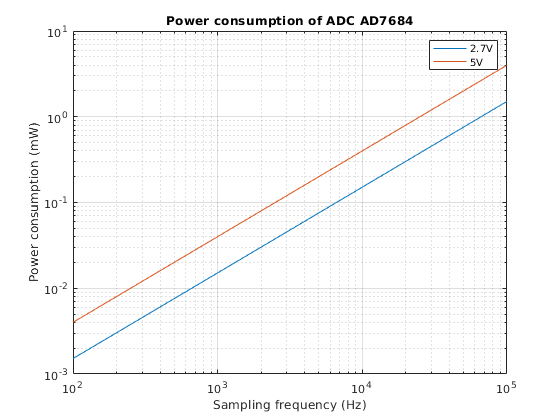

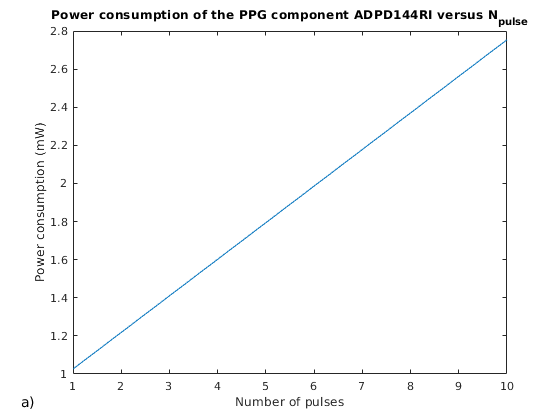


% Changing the number of pulses
for i=1:10
    num_pulses=i;
    Ivdd_ave=(2*Tslot*(Iafe+Iproc)+(Ts-2*Tslot)*Istandby)/Ts;
    Iled_ave=(Tledpulse/Ts)*num_pulses*Iled;
    Pppg=Ivdd_ave*Vdd+2*Iled_ave*Vled;
    Pout(i)=Pppg;
end
figure
plot(1:10,Pout)
title('Power consumption of the PPG component ADPD144RI versus N_{pulse}')
xlabel('Number of pulses')
ylabel('Power consumption (mW)')
annonation_save('a)',"Fig10.10a.jpg", 1);

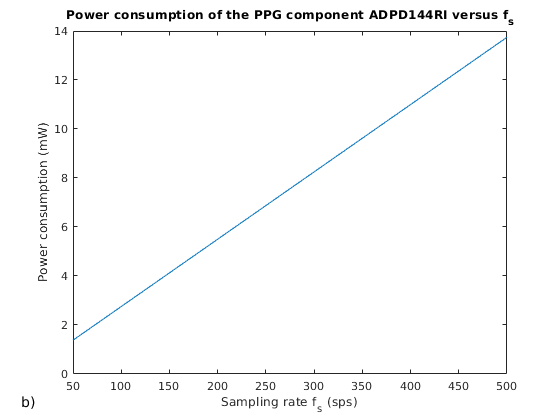


% Changing the data rate
for i=1:10
    fs=i*50; % data rate
    Ts=1/fs;
  
    Ivdd_ave=(2*Tslot*(Iafe+Iproc)+(Ts-2*Tslot)*Istandby)/Ts;
    Iled_ave=(Tledpulse/Ts)*num_pulses*Iled;
    Pppg=Ivdd_ave*Vdd+2*Iled_ave*Vled;
    Pout(i)=Pppg;
end
figure
plot(50:50:500,Pout)
title('Power consumption of the PPG component ADPD144RI versus f_s')
xlabel('Sampling rate f_s (sps)')
ylabel('Power consumption (mW)')
annonation_save('b)',"Fig10.10b.jpg", 1);

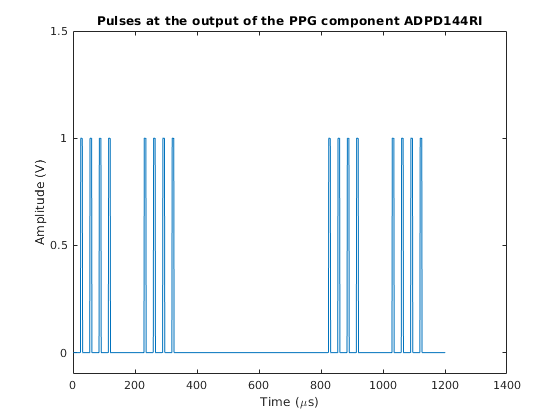

% Generating PPG pulses 
t=0:1e-6:1200e-6;
DR=100; % data rate
T_DR=1/DR; 
num_pulses=4;
Tpulseperiod=30e-6;
Tprocessingtime=60e-6;
Tledpulse=5e-6;

T_sample=0;
out=zeros(1,length(t));
for j=1:2
    for i=0:num_pulses-1
        interval=T_sample+Toffset+i*Tpulseperiod:1e-6:T_sample+Toffset+i*Tpulseperiod+Tledpulse;
        out(round(interval*1e6))=ones(1,length(interval));
    end
    Tslot=Toffset+Tpulseperiod*num_pulses+Tprocessingtime;
    for i=0:num_pulses-1
        interval=T_sample+Tslot+Toffset+i*Tpulseperiod:1e-6:T_sample+Tslot+Toffset+i*Tpulseperiod+Tledpulse;
        out(round(interval*1e6))=ones(1,length(interval));
    end
    T_sample=T_sample+800e-6;
end
figure
plot(out)
title('Pulses at the output of the PPG component ADPD144RI')
xlabel('Time (\mus)')
ylabel('Amplitude (V)')
ylim([-0.1,1.5])
exportgraphics(gcf,"Fig10.9_smartdraw.jpg", 'Resolution',600)

Microcontroller

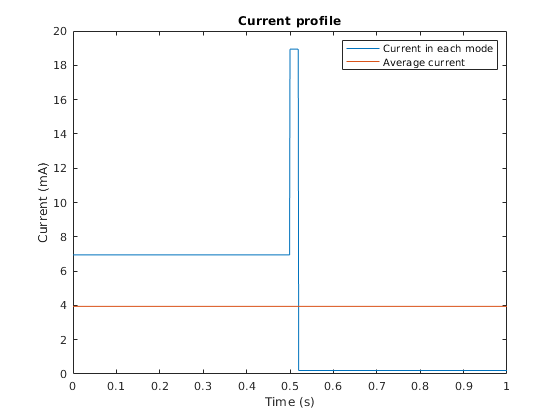

IRTC= 1.3e-3; %[mA] 
Itimer=6e-3; 
II2C=126e-3;
Iradio=12;
ICPUnormal=6.81;
ICPUstop=204e-3;
ICPUVLLS=0.56e-3;
Tnormal=0.5;
Tstp=0.48;
Tcomm=0.02;

Itot_normal=ICPUnormal+IRTC+Itimer+II2C;
Itot_comm=Itot_normal+Iradio;
Itot_stop=ICPUstop+IRTC;

t=0:0.001:1;

for i=1:length(t)
    if t(i)<Tnormal
        Iout(i)=Itot_normal;
    elseif t(i)<Tnormal+Tcomm
        Iout(i)=Itot_comm;
    else 
        Iout(i)=Itot_stop;
    end
end
figure
plot(t,Iout)
hold on
plot(t,mean(Iout)*ones(1,length(t)))
title('Current profile')
xlabel('Time (s)')
ylabel('Current (mA)')
legend(['Current in each mode'],['Average current'])
exportgraphics(gcf,"Fig10.11.jpg", 'Resolution',600)

## Computing the power at the output

% Case 1
IRTC= 1.3e-3; %[mA] 
Itimer=6e-3; 
II2C=126e-3;
Iradio=6.3;
ICPUnormal=6.71;
ICPUstop=204e-3;
ICPUVLLS=0.56e-3;
Tnormal=0.025;
Tstp=0.225;
Tcomm=0.02;

Itot_normal=ICPUnormal+IRTC+Itimer+II2C;
Itot_comm=Itot_normal+Iradio;
Itot_stop=ICPUstop+IRTC;
Iproc_ave=(Itot_normal*Tnormal+Itot_comm*Tcomm+Itot_stop*Tstp)/(Tnormal+Tstp+Tcomm);

P=2.75 +Iproc_ave*1.2+0.05*2.05

P = 4.9865

Ptotal=P/0.85

Ptotal = 5.8664

TotalDuration=3.6*1000/Ptotal

TotalDuration = 613.6618

days=floor(TotalDuration/24)

days = 25

hours=TotalDuration-days*24

hours = 13.6618


% Case 2
Tnormal=0.5;
Tstp=0.492;
Tcomm=0.008;

Itot_normal=ICPUnormal+IRTC+Itimer+II2C;
Itot_comm=Itot_normal+Iradio;
Itot_stop=ICPUstop+IRTC;
Iproc_ave=(Itot_normal*Tnormal+Itot_comm*Tcomm+Itot_stop*Tstp)/(Tnormal+Tstp+Tcomm);

P=2.75 +Iproc_ave*1.2+0.05*2.05

P = 7.2059

Ptotal=P/0.85

Ptotal = 8.4775

TotalDuration=3.6*1000/Ptotal

TotalDuration = 424.6541

days=floor(TotalDuration/24)

days = 17

hours=TotalDuration-days*24

hours = 16.6541